# `Showcase of some real- and reciprocal-space structures`

close all; clear all;
help get_crystal_props;

  [realStr, reciStr] = get_crystal_props(crystal_args, plot_results)
    This is a function that extracts the crystallographic vectors
    of a general crystal structure in both real- and reciprocal-
    space based on the inputs. All 14 Bravais lattices can be 
    defined, including primitive-, base-, face- and body-centered
    lattices. The outputs are two MATLAB structures that contain
    all of the real- and reciprocal-space data.
 
    LIST OF AVAIABLE CRYSTAL STRUCTURES:
        - CUB-cP-Oh    : Simple Cubic
        - CUB-cI-Oh    : Body-Centered Cubic
        - CUB-cF-Oh    : Face-Centered Cubic
        - HEX-hP-D6h   : Simple Hexagonal
        - RHL-hR-D3d   : Simple Rhombahedral
        - TET-tP-D4h   : Simple Tetragonal
        - TET-tI-D4h   : Body-Centered Tetragonal
        - ORC-oP-D2h   : Simple Orthorhombic
        - ORC-oS-D2h   : Base-Centered Orthorhombic
        - ORC-oI-D2h   : Body-Centered Orthorhombic
        - ORC-oF-D2h   : Face-Centered Or

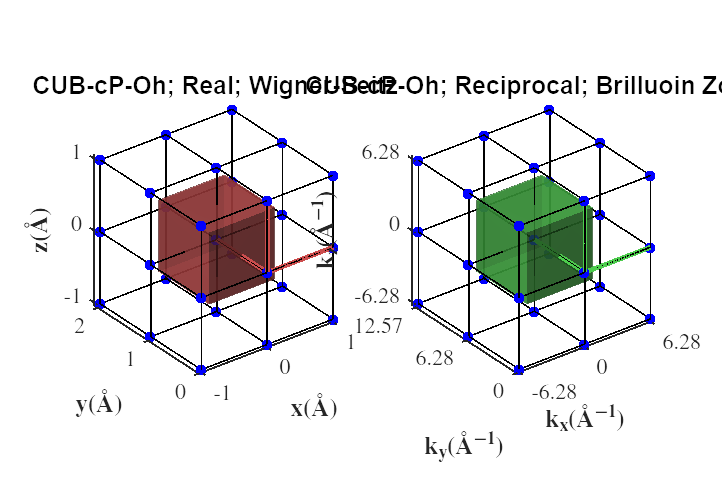

[realStr, reciStr] = get_crystal_props("CUB-cP-Oh", 1);

## `Extracting Brilluoin Zone slices`

help get_crystal_props;

  [realStr, reciStr] = get_crystal_props(crystal_args, plot_results)
    This is a function that extracts the crystallographic vectors
    of a general crystal structure in both real- and reciprocal-
    space based on the inputs. All 14 Bravais lattices can be 
    defined, including primitive-, base-, face- and body-centered
    lattices. The outputs are two MATLAB structures that contain
    all of the real- and reciprocal-space data.
 
    LIST OF AVAIABLE CRYSTAL STRUCTURES:
        - CUB-cP-Oh    : Simple Cubic
        - CUB-cI-Oh    : Body-Centered Cubic
        - CUB-cF-Oh    : Face-Centered Cubic
        - HEX-hP-D6h   : Simple Hexagonal
        - RHL-hR-D3d   : Simple Rhombahedral
        - TET-tP-D4h   : Simple Tetragonal
        - TET-tI-D4h   : Body-Centered Tetragonal
        - ORC-oP-D2h   : Simple Orthorhombic
        - ORC-oS-D2h   : Base-Centered Orthorhombic
        - ORC-oI-D2h   : Body-Centered Orthorhombic
        - ORC-oF-D2h   : Face-Centered Or

**(1.0)     :    CUB-cP-Oh    :    Simple Cubic (sc)**

[realStr, reciStr] = get_crystal_props("CUB-cP-Oh", 1);

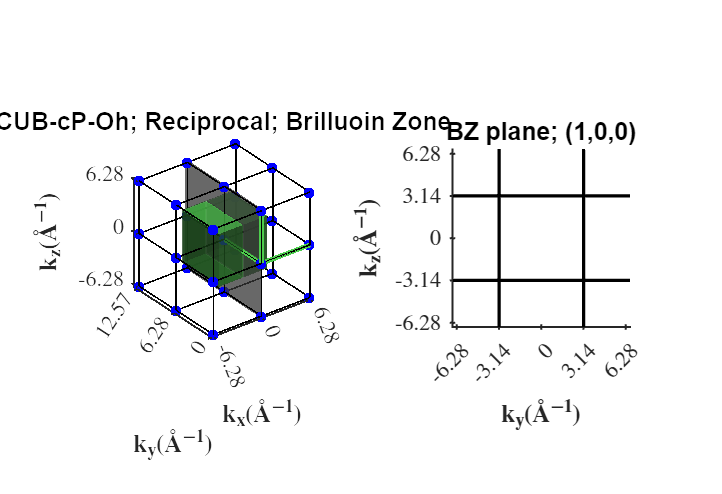

get_bz_slice(reciStr, [1,0,0], 1);

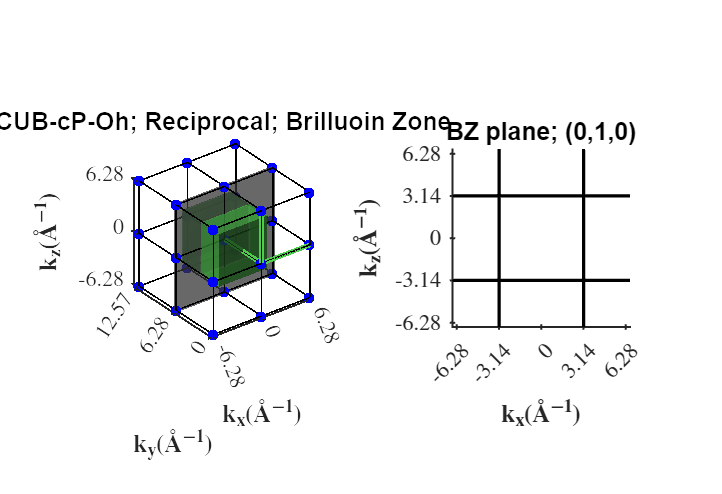

get_bz_slice(reciStr, [0,1,0], 1);

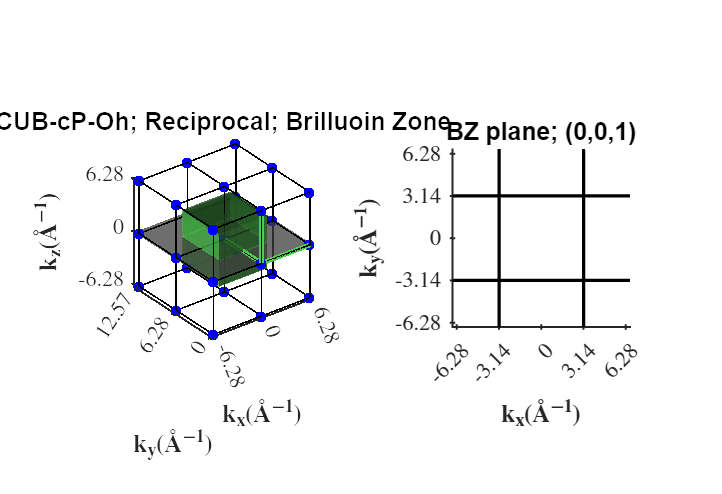

get_bz_slice(reciStr, [0,0,1], 1);

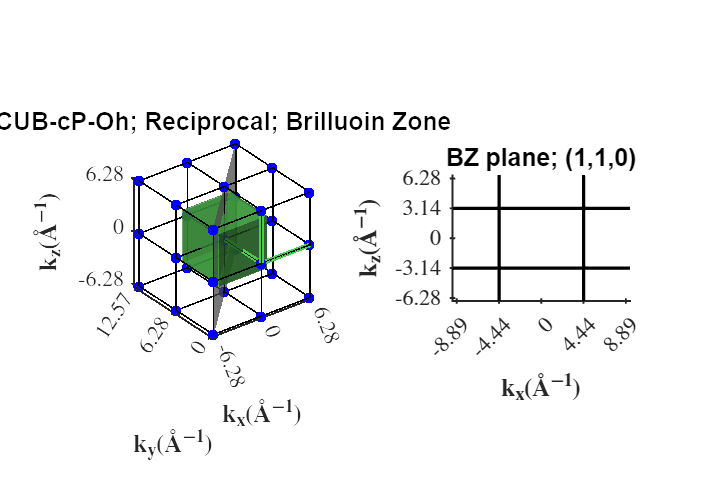

bzSlice = struct with fields:
          crystal: "CUB-cP-Oh"
    crystal_plane: [1 1 0]
             area: 55.8309
               X0: [6×1 double]
               Y0: [6×1 double]
                X: {1×169 cell}
                Y: {1×169 cell}
               gX: 8.8858
               gY: 6.2832


bzSlice = get_bz_slice(reciStr, [1,1,0], 1)

**(1.1)     :    CUB-cF-Oh  :    Face-Centered Cubic (fcc)**

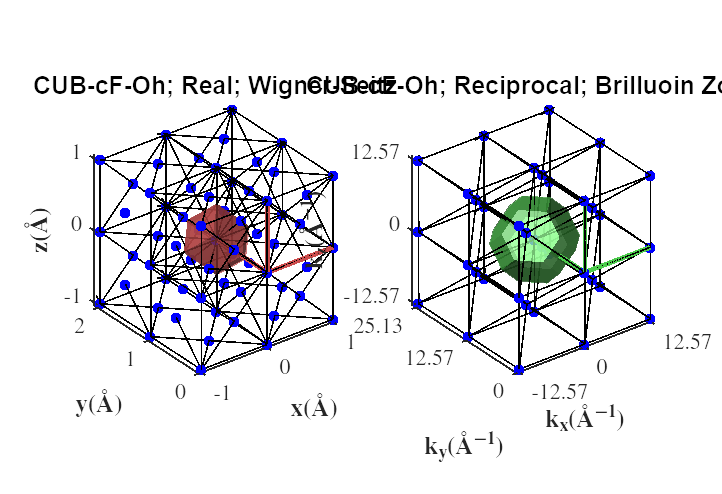

[realStr, reciStr] = get_crystal_props("CUB-cF-Oh", 1);

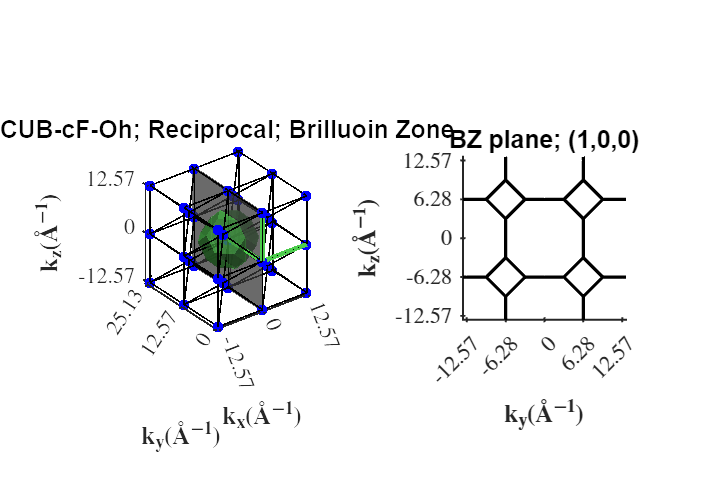

get_bz_slice(reciStr, [1,0,0], 1);

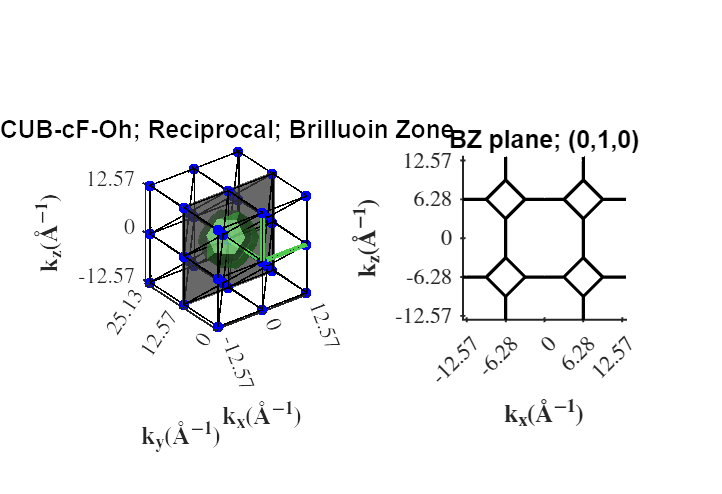

get_bz_slice(reciStr, [0,1,0], 1);

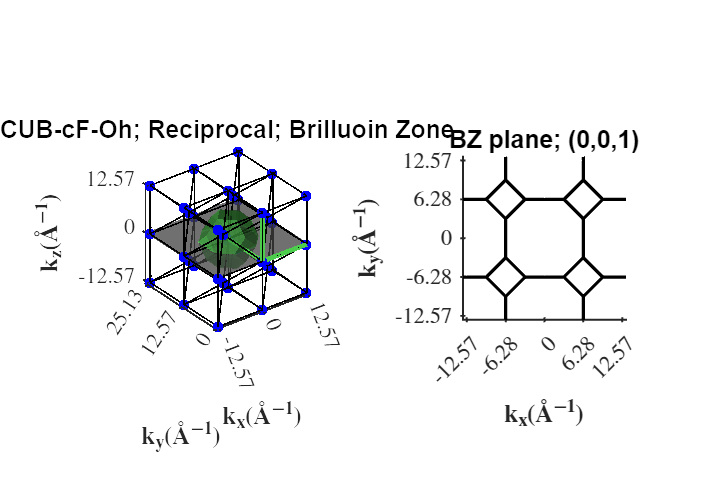

get_bz_slice(reciStr, [0,0,1], 1);

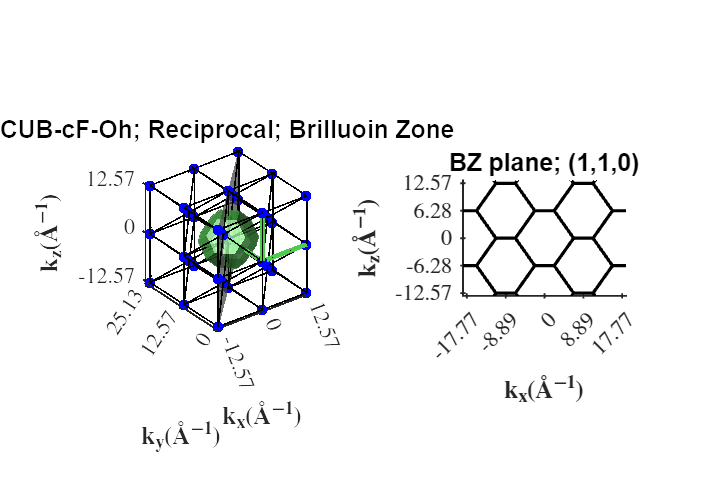

bzSlice = struct with fields:
          crystal: "CUB-cF-Oh"
    crystal_plane: [1 1 0]
             area: 111.6618
               X0: [13×1 double]
               Y0: [13×1 double]
                X: {1×169 cell}
                Y: {1×169 cell}
               gX: 17.7715
               gY: 12.5664


bzSlice = get_bz_slice(reciStr, [1,1,0], 1)

**(1.2)     :    CUB-cI-Oh   :    Body-Centered Cubic (bcc)**

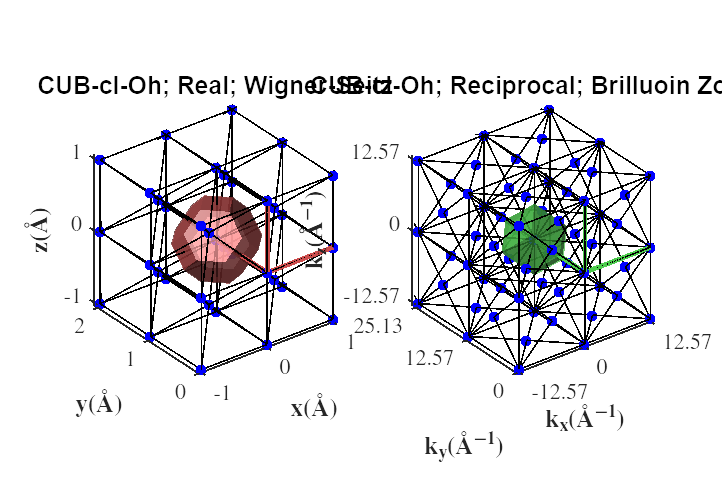

[realStr, reciStr] = get_crystal_props("CUB-cI-Oh", 1);

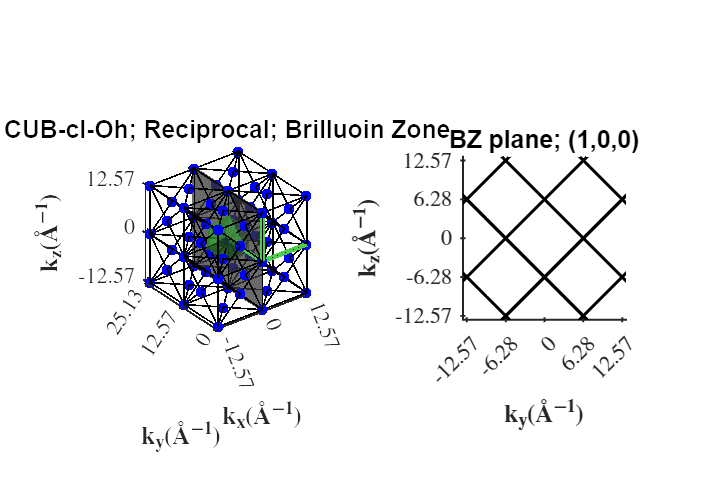

bzSlice = get_bz_slice(reciStr, [1,0,0], 1);

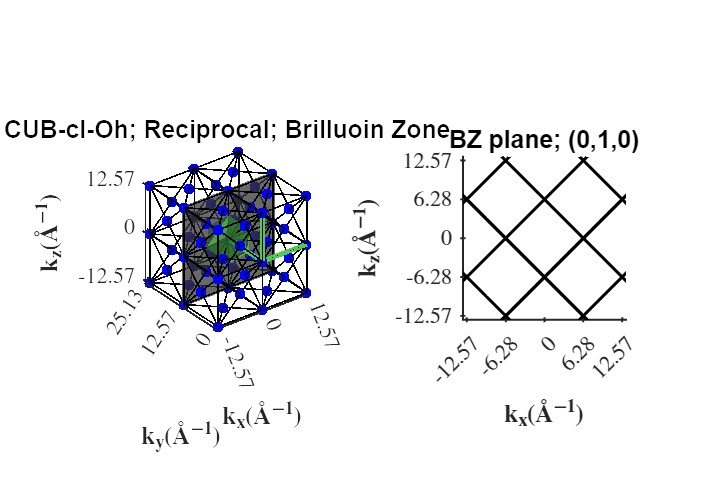

bzSlice = get_bz_slice(reciStr, [0,1,0], 1);

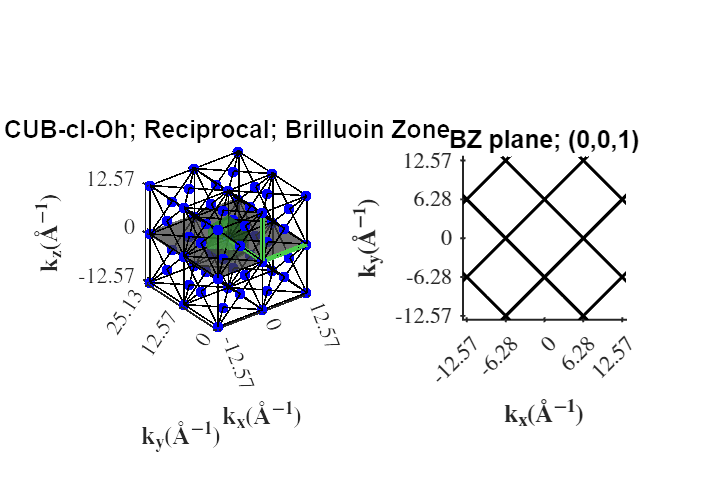

bzSlice = get_bz_slice(reciStr, [0,0,1], 1);

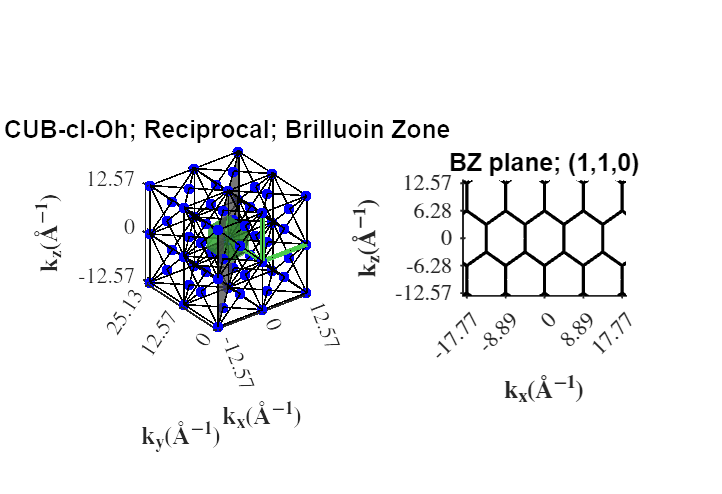

bzSlice = get_bz_slice(reciStr, [1,1,0], 1);

**(1.3)     :    HEX-hP-D6h    :    Hexagonal (hex)**

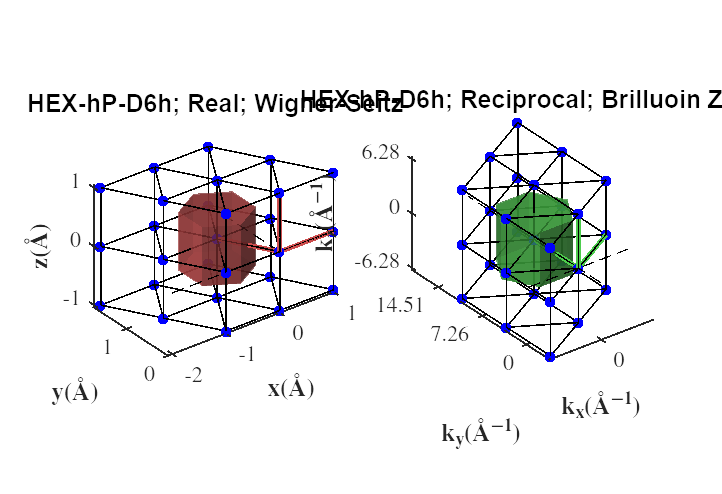

[realStr, reciStr] = get_crystal_props("HEX-hP-D6h", 1);

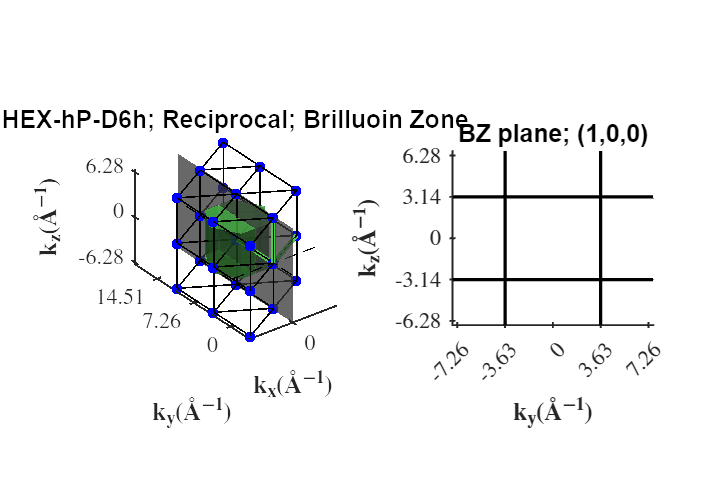

bzSlice = get_bz_slice(reciStr, [1,0,0], 1);

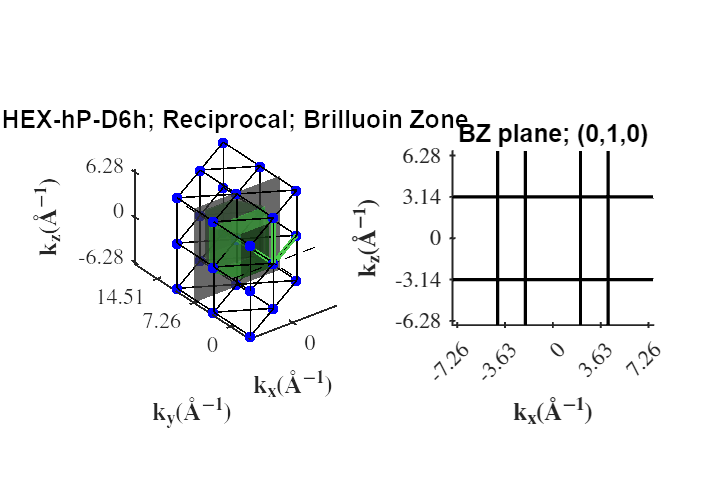

bzSlice = get_bz_slice(reciStr, [0,1,0], 1);

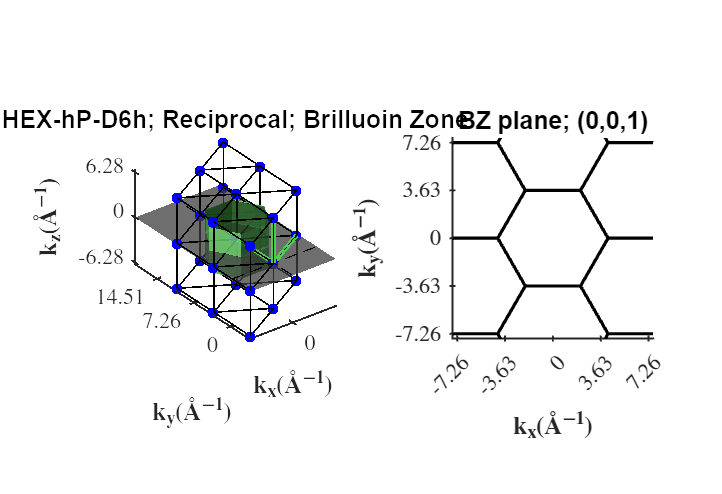

bzSlice = get_bz_slice(reciStr, [0,0,1], 1);

## `Brilluoin Zone slices : Linear Transformations`

**(2.0)     :    CUB-cP-Oh    :    Simple Cubic (sc)**

[realStr, reciStr] = get_crystal_props("CUB-cP-Oh", 1);

get_bz_slice(reciStr, [0,0,1], 1);

bzSlice         = get_bz_slice(reciStr, [1,1,0], 1);

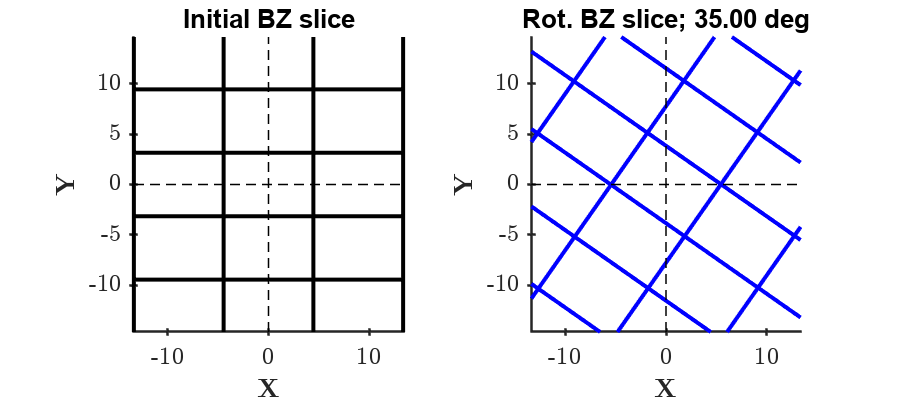

bzSlice_rot     = rotate_bz_slice(bzSlice, {35}, 1);

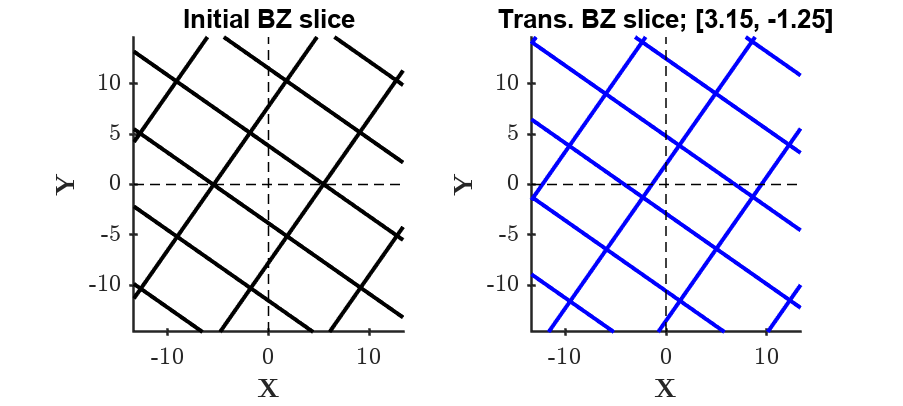

bzSlice_trans   = translate_bz_slice(bzSlice_rot, {3.15, -1.25}, 1);

## `Miscellaneous functions`

get_crystal_type([1,1,1], [90,90,90])

ans = "CUB-cP-Oh"

get_crystal_type([1,1,1], [90,90,120])

ans = "HEX-hP-D6h"

get_crystal_type([2,2,2], [45,45,45])

ans = "RHL-hR-D3d"

#### (A) Plotting truncated octahedron

fig = figure(); fig.Position = [10 10 800, 600];  hold on; 
plot_TruncOctahedron(); 
camlight(-90, 20);

#### (B) Plotting 3D silicon valleys embedded in Brillouin Zone

fig = figure(); fig.Position = [10 10 800, 600]; hold on;
% -- Plotting the axes lines
L = 0.75; X = 0.95;
M111_col = [0.8, 0.4, 0];
X100_col = [0.1,0.6,0.1];
G001_col = [0.6,0.1,0.6];
line([0, 0]*X, [0, 0]*X, [-1, 1]*X, 'Color', G001_col, 'LineWidth', 1, 'Linestyle', '-');
line([0, 0]*X, [-1, 1]*X, [0, 0]*X, 'Color', X100_col, 'LineWidth', 1, 'Linestyle', '-');
line([-1, 1]*X, [0, 0]*X, [0, 0]*X, 'Color', X100_col, 'LineWidth', 1, 'Linestyle', '-');
% - (1st ZONE) PLOTTING THE SILICON VALLEYS and BZ
plot_SiCBValleys_3D(0.2,[],[0.03, 0.03, -0.25]);
plot_fccBZ_3D();
% Formatting the figure
axis([-1, 1, -1, 1, -1, 1]*1.2); view([-65, 16]); camlight(-0, 20);
axis off;

#### (C) Plotting 2D silicon valleys embedded in Brillouin Zone

fig = figure(); fig.Position = [10 10 800, 600]; hold on;
% -- Plotting the axes lines
line([0 0], [-1, 1]*5, [0 0], 'Color', [0 0 0], 'LineWidth', 1, 'Linestyle', '--');
line([-1 1]*5, [0 0], [0 0], 'Color', [0 0 0], 'LineWidth', 1, 'Linestyle', '--');
line([0, 0], [0 0], [-1 1]*5, 'Color', [0 0 0], 'LineWidth', 1, 'Linestyle', '--');
% - (1st ZONE) PLOTTING THE SILICON VALLEYS and BZ
plot_SiCBValleys_q2D(0.3,[],[0.03, 0.03, -0.25]);
plot_fccBZ_3D();
% Formatting the figure
axis([-1, 1, -1, 1, -1, 1]*1.2); view([-65, 16]); camlight(-0, 20);
axis off;

#### (C) Plotting 3D germanium valleys embedded in Brillouin Zone

fig = figure(); fig.Position = [10 10 800, 600]; hold on;
% -- Plotting the axes lines
L = 0.75; X = 0.95;
M111_col = [0.8, 0.4, 0];
X100_col = [0.1,0.6,0.1];
G001_col = [0.6,0.1,0.6];
line(-1*[-1, 1]*L, [-1, 1]*L, [-1, 1]*L, 'Color', M111_col, 'LineWidth', 1, 'Linestyle', '-');
line([-1, 1]*L, -1*[-1, 1]*L, [-1, 1]*L, 'Color', M111_col, 'LineWidth', 1, 'Linestyle', '-');
line([-1, 1]*L, [-1, 1]*L, -1*[-1, 1]*L, 'Color', M111_col, 'LineWidth', 1, 'Linestyle', '-');
line([-1, 1]*L, [-1, 1]*L, [-1, 1]*L, 'Color', M111_col, 'LineWidth', 1, 'Linestyle', '-');
line([0, 0]*X, [0, 0]*X, [-1, 1]*X, 'Color', G001_col, 'LineWidth', 1, 'Linestyle', '-');
line([0, 0]*X, [-1, 1]*X, [0, 0]*X, 'Color', X100_col, 'LineWidth', 1, 'Linestyle', '-');
line([-1, 1]*X, [0, 0]*X, [0, 0]*X, 'Color', X100_col, 'LineWidth', 1, 'Linestyle', '-');
% - (1st ZONE) PLOTTING THE SILICON VALLEYS and BZ
plot_SiCBValleys_3D(0.20,[],[0.05, 0.05, -0.05]);
plot_fccBZ_3D(5.657);
plot_GeCBValleys_3D(0.3);
% Formatting the figure
axis([-1, 1, -1, 1, -1, 1]*1.2); view([-65, 16]); camlight(-0, 20); axis off;